**Understanding Inverse Fourier Transforms Through Race Car Engine Vibrations**

I studied how signals can be analyzed in the frequency domain and subsequently reconstructed in the time domain without losing critical information. To make the analysis relatable, I modeled race car engine vibrations using a combination of sinusoidal components and noise. This exercise highlighted the importance of preserving both the real and imaginary parts of the frequency representation during reconstruction, as the loss of either can lead to significant distortion.

I began by defining a synthetic signal that mimics the vibrations of a race car engine. The signal included two dominant vibration modes, represented by sine waves of distinct frequencies, and Gaussian noise to reflect real-world randomness. This step ensured that the simulated data was realistic and representative of actual engine behavior.

To analyze the signal, I applied the Fast Fourier Transform (FFT), which transformed the time-domain signal into the frequency domain. This provided insights into the vibration modes' frequency characteristics, encoded in the real (magnitude) and imaginary (phase) components of the transform.

I used the Inverse Fast Fourier Transform (IFFT) to reconstruct the original signal from its frequency representation. The reconstruction demonstrated that preserving both the real and imaginary parts is essential for maintaining the integrity of the signal. To simulate data loss, I also reconstructed the signal using only the real part, resulting in a distorted signal.

Through visualization, I compared the original signal, the fully reconstructed signal, and the distorted signal. The fully reconstructed signal matched the original closely, while the signal reconstructed from the real part only was severely degraded. This reinforced the importance of both magnitude and phase in signal reconstruction.

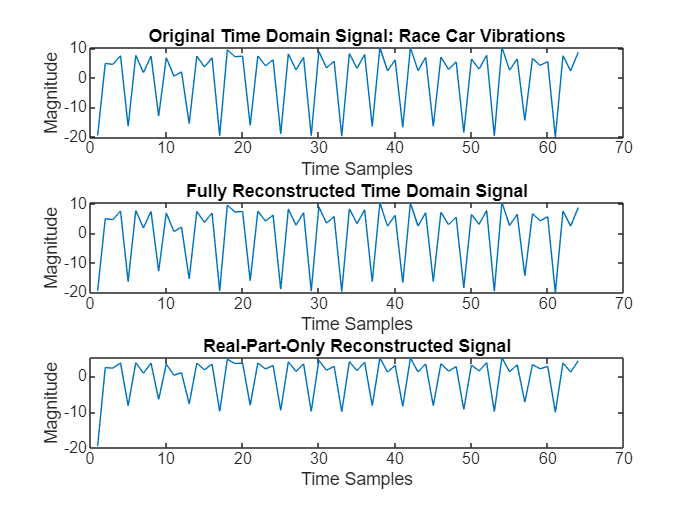

% Step 1: Define the signal parameters
A1 = 10; % I set the amplitude of the first vibration mode to 10 to represent its power.
A2 = 10; % I used the same amplitude for the second vibration mode to ensure equal contributions.
w1 = 2 * pi * 0.5; % I defined the angular frequency for the first mode, simulating a slower vibration.
w2 = 2 * pi * 0.75; % I chose a slightly higher angular frequency for the second mode to differentiate it.
Ts = 1; % I selected a sampling time of 1 second for simplicity in calculations.
N = 64; % I generated 64 samples to capture the key dynamics of the engine vibrations.
K = 1; % I modeled a single realization of the signal to keep the analysis straightforward.
sgm = 2; % I added Gaussian noise with a standard deviation of 2 to simulate real-world randomness.

% Step 2: Generate the time index matrix and random phases
n = repmat((0:N-1).', 1, K); % I created a matrix of time indices for each sample point to structure the signal.
phi1 = repmat(rand(1, K) * 2 * pi, N, 1); % I generated random phases for the first vibration mode to introduce variability.
phi2 = repmat(rand(1, K) * 2 * pi, N, 1); % I did the same for the second vibration mode.

% Step 3: Construct the engine vibration signal
engine_vibrations = A1 * sin(w1 * n * Ts + phi1) + A2 * sin(w2 * n * Ts + phi2) + sgm * randn(N, K);
% I combined the sine waves and noise to create a realistic representation of engine vibrations.

% Step 4: Perform the Fourier Transform
NFFT = 256; % I chose an FFT length of 256 (a power of 2) to optimize computation and include zero-padding.
F = fft(engine_vibrations, NFFT); % I transformed the signal into the frequency domain using FFT.

% Step 5: Reconstruct the signal using the Inverse Fourier Transform
TD = ifft(F, NFFT); % I applied the IFFT to reconstruct the time-domain signal, preserving both real and imaginary parts.

% Step 6: Reconstruct the signal using only the real part
R = real(F); % I extracted only the real part of the frequency domain representation to simulate data loss.
TDR = ifft(R, NFFT); % I reconstructed the signal using only the real part, leading to a distorted result.

% Step 7: Visualize the results
figure;

% Original Signal
subplot(3, 1, 1);
plot(engine_vibrations); % I plotted the original time-domain signal to establish a reference.
xlabel('Time Samples'); % I labeled the x-axis to show the time samples.
ylabel('Magnitude'); % I labeled the y-axis to represent the vibration magnitude.
title('Original Time Domain Signal: Race Car Vibrations'); % I added a descriptive title.

% Fully Reconstructed Signal
subplot(3, 1, 2);
plot(TD(1:N)); % I plotted the reconstructed signal using the IFFT with both real and imaginary parts.
xlabel('Time Samples'); % I labeled the x-axis for time samples.
ylabel('Magnitude'); % I labeled the y-axis for magnitude.
title('Fully Reconstructed Time Domain Signal'); % I added a title to indicate the result.

% Real-Part-Only Reconstruction
subplot(3, 1, 3);
plot(TDR(1:N)); % I plotted the signal reconstructed from the real part only.
xlabel('Time Samples'); % I labeled the x-axis for time samples.
ylabel('Magnitude'); % I labeled the y-axis for magnitude.
title('Real-Part-Only Reconstructed Signal'); % I added a title to highlight the distortion.